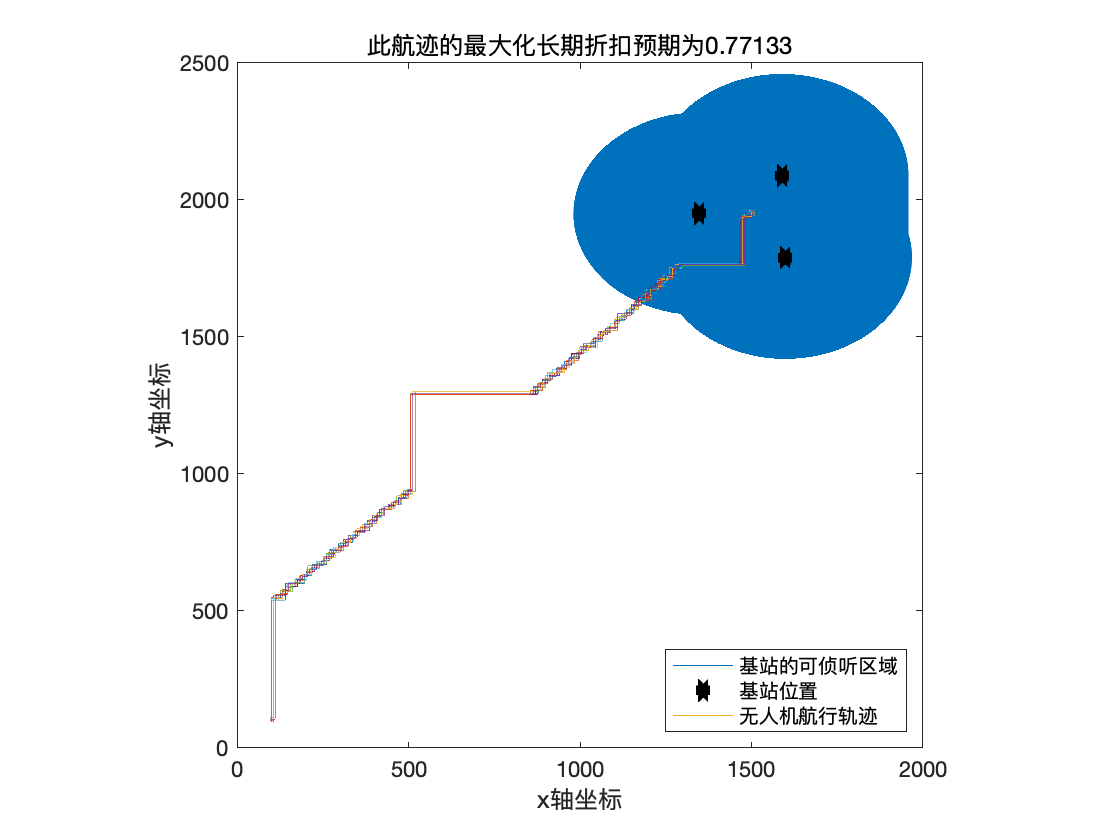

clear all;
clc;

%{
粒子群算法核心部分：
v(k)=wv(k-1)+c1r1(pbest-x(k-1))+c2r2(gbest-x(k-1))
x(k+1)=x(k)+v(k)
%}

global H;
global P;
global sig2;
global K;
global pos

%设置基本常量
H=150;%设置无人机飞行高度H,(m)
l0=10;%设置无人机飞行速度l0,(m/s)
P=10;%设置基站发送功率,(W)
sig2=2*1E-5;%设置噪声功率σ2 = 2×10-5,(w)
rho=3.1623;%设置门限ρ1，ρ2
max=1000;%定义搜索次数上限（实际上可能早就早于达到搜索上限之前找到了最佳点）
t=1/2;%定义单次搜索时间
left=[-l0*t,0];
right=[l0*t,0];
up=[0,l0*t];
down=[0,-l0*t];
ins=[up;down;left;right];%分别定义上下左右指令


K=3;%假设共有K个基站
gamma=0.5;%设置折扣因子γ
a0=100;%设置无人机起始横坐标
b0=100;%设置无人机起始纵坐标

%设置基础变量
drone=30;%设置一次放出的无人机数量
x=zeros(max,2,drone);%无人机第i次搜索之后的坐标,其中第一列为横坐标，第二列为纵坐标
v=zeros(max,2,drone);%设置速度更新数组
pbest=zeros(drone,2);%设置自身最佳历史位置

%设置粒子群算法核心参数
w=0.8;
c1=1.49445;
c2=1.49445;

pos=zeros(K,2);%基站的坐标,其中第一列为横坐标，第二列为纵坐标
pos(1,:)=[1350, 1950];
pos(2,:)=[1600, 1790];
pos(3,:)=[1590, 2090];

%生成可侦听区域半径
r_safe=sqrt(P/(rho*sig2)-H^2);%以基站为圆心的可侦听的区域的半径
theta = linspace(0,2*pi,10000);%计算可侦听区域
A(:,1) = pos(1,1)+r_safe*cos(theta);
A(:,2) = pos(1,2)+r_safe*sin(theta);
B(:,1) = pos(2,1)+r_safe*cos(theta);
B(:,2) = pos(2,2)+r_safe*sin(theta);
C(:,1) = pos(3,1)+r_safe*cos(theta);
C(:,2) = pos(3,2)+r_safe*sin(theta);
D = union(A,B,'rows');%合并所有基站的可侦听区域
D = union(C,D,'rows');


R=zeros(max,drone);%第i个时刻的和信息速率评价函数

%定义第一次搜索点：
for j=1:1:drone
    pbest(j,:)=[a0,b0];
end

gbest=[a0,b0];

for j=1:1:drone
    x(1,:,j)=[a0,b0]+ins(1+floor(4*rand),:);
    v(1,:,j)=ins(1+floor(4*rand),:);
    if (getR(pbest(j,:))<getR(x(1,:,j)))
        pbest(j,:)=x(1,:,j);
    end
    if (pbest(j,:)>gbest)
        gbest=pbest(j,:);
    end
    R(1,j)=getR(x(1,:,j));
end



t_1st=0;%初始化第一次进入可侦听区域的时间

index=zeros(drone,1);

for i=2:1:max
    for j=1:1:drone
        
        if(t_1st==0)%判断第一次进入可侦听区域的时间
            if(norm(x(i,:,1)-pos(1,:))<=r_safe||norm((x(i,:,1)-pos(2,:)))<=r_safe||norm((x(i,:,1)-pos(3,:)))<=r_safe)
                t_1st=i*t;
            end
        end
        

        v(i,:,j)=w*v(i-1,:,j)+c1*rand*(pbest(j,:)-x(i-1,:,j))+c2*rand*(gbest-x(i-1,:,j));%更新速度v(k)
        if(abs(v(i,1,j))>abs(v(i,2,j))&&v(i,1,j)>0)%判断速度V，从而修正搜索方向
            v(i,:,j)=right;
        elseif (abs(v(i,1,j))>abs(v(i,2,j))&&v(i,1,j)<0)
            v(i,:,j)=left;
        elseif (abs(v(i,1,j))<abs(v(i,2,j))&&v(i,2,j)>0)
            v(i,:,j)=up;
        elseif (abs(v(i,1,j))<abs(v(i,2,j))&&v(i,2,j)<0)
            v(i,:,j)=down;
        else
            v(i,:,j)=0;
        end
        x(i,:,j)=x(i-1,:,j)+v(i,:,j);
        
        if (getR(pbest(j,:))<getR(x(i,:,j)))
            pbest(j,:)=x(i,:,j);
        end
        if (getR(gbest)<getR(pbest(j,:)))
            gbest=pbest(j,:);
        end
        
        R(i,j)=getR(x(i,:,j));
        
    end
end
    
    


for i=1:1:max
    for j=1:1:drone
        if (~index(j))
            if(x(i,:,j)==[1505,1955])
                index(j)=i;
            end
        end
    end
    
end

E=0;

for i=1:1:index(drone)
    E=E+power(gamma,i-1)*R(i,drone);
end

plot(D(:,1),D(:,2));hold on;%绘制可被侦听区域
s=scatter(pos(:,1),pos(:,2),"*");%绘制基站位置
s.LineWidth = 5;
s.MarkerEdgeColor = 'black';

for j=1:1:drone

plot(x(1:index(j),1,j),x(1:index(j),2,j));%绘制航迹图

axis square;
title(['此航迹的最大化长期折扣预期为',num2str(E)]);
xlabel('x轴坐标') 
ylabel('y轴坐标') 
end
legend({'基站的可侦听区域','基站位置','无人机航行轨迹'},'Location','southeast')
hold off;


disp(['第一次进入可侦听区域的时间为:',num2str(t_1st)]);

第一次进入可侦听区域的时间为:261.5



disp(['到达最佳侦听点的时刻为:',num2str(t*index(drone))]);

到达最佳侦听点的时刻为:326


function Rtemp=getR(x)%得到和信息速率评价
global H;
global P;
global sig2;
global K;
global pos

d2=zeros(1,K);%无人机距离基站的距离
h=zeros(1,K);%基站与无人机之间的信道功率增益
Rk=zeros(1,K);%无人机的通信基站的信息速率评价函数分量
sum=0;

for j=1:1:K
    d2(j)=H^2+(x(1)-pos(j,1))^2+(x(2)-pos(j,2))^2;
    h(j)=1/d2(j);
    Rk(j)=log2(1+P*h(j)/sig2);
    sum=sum+Rk(j);
end

Rtemp=sum;
end
